# Parking car simulation

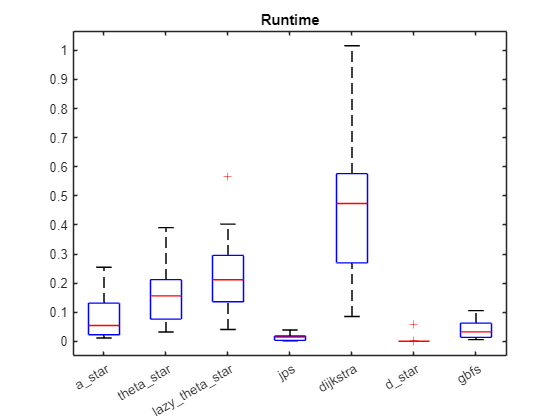

clear all;
clc;

% Better cost function
function totalDistance = sumDistances(points)
    % Initialize the total distance
    totalDistance = 0;
    
    % Loop over the points and calculate the distance between consecutive points
    for i = 1:(size(points, 1) - 1)
        % Calculate Euclidean distance between points(i,:) and points(i+1,:)
        dist = sqrt((points(i+1, 1) - points(i, 1))^2 + (points(i+1, 2) - points(i, 2))^2);
        
        % Add the distance to the total
        totalDistance = totalDistance + dist;
    end
end

addpath(genpath("./utils/"), genpath("./global_planner/"));
load("grid_map_parking.mat");
map_size = size(grid_map);
G = 1; 

planner_names = ["a_star", "theta_star", "lazy_theta_star", "jps", "dijkstra", "d_star", "gbfs"];

rng("default")

parking_spots = [10,29 ; 6,21 ; 11,17 ; 6,7 ; 14,29 ; 17,4; 11,11 ; 17,18 ; 4,27];

times = [];
costs = [];


% Run n tests
for i = 1:30
    start = [3, 2];
    
    rePlan = randi([0, 1]);
    % Get random parking spots
    goal = parking_spots(randi(size(parking_spots, 1)),:);
    goal2 = parking_spots(randi(size(parking_spots, 1)),:);
    while goal2 == goal % Make sure the spots are not the same
        goal2 = parking_spots(randi(size(parking_spots,1)),:);
    end
    
    tmpTimes = [];
    tmpCosts = [];
    for iplanner = 1:length(planner_names)
        planner = str2func(planner_names(iplanner));
        tic;
        [path, flag, cost, expand] = planner(grid_map, start, goal);
        time1 = toc;
        
        time2 = 0;
        path2 = [];
        if rePlan == 1
            newstart = [path(end - 3, 1), path(end - 3, 2)];
            tic;
            [path2, flag2, cost2, expand2] = planner(grid_map, newstart, goal2);
            time2 = toc;
        end
    
        tmpTimes = [tmpTimes, time1 + time2];
        tmpCosts = [tmpCosts, sumDistances(path) + sumDistances(path2)];
    end
    times = [times; tmpTimes];
    costs = [costs; tmpCosts];
end


boxplot(times, "Labels", planner_names);
title("Runtime")

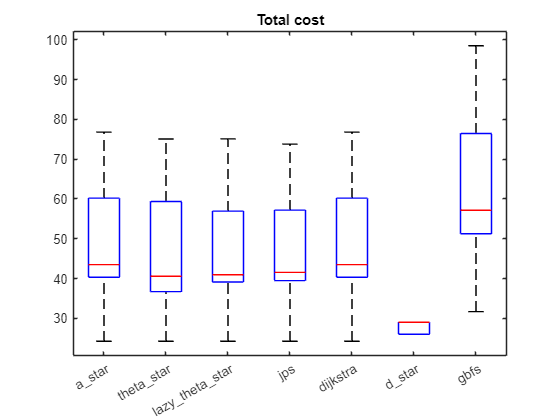

boxplot(costs, "Labels", planner_names);
title("Total cost")